# Differentiation

wiki: [https://en.wikipedia.org/wiki/Numerical_differentiation](https://en.wikipedia.org/wiki/Numerical_differentiation)


$$$$
\left. \frac{d^n}{dx^n}f\left( x \right) \right|_{x=a}
$$
$$


- function: $$
f
$
$

- $$x$$ value: $a$

- order: $n$

## Parameter

hf1 = @(x) x.^3 + sin(x).^2;
hf1_1 = @(x) 3*x.^2 + 2*sin(x).*cos(x);
hf1_2 = @(x) 6*x + 4*cos(x).^2 - 2;
a = rand(1);

## Graph

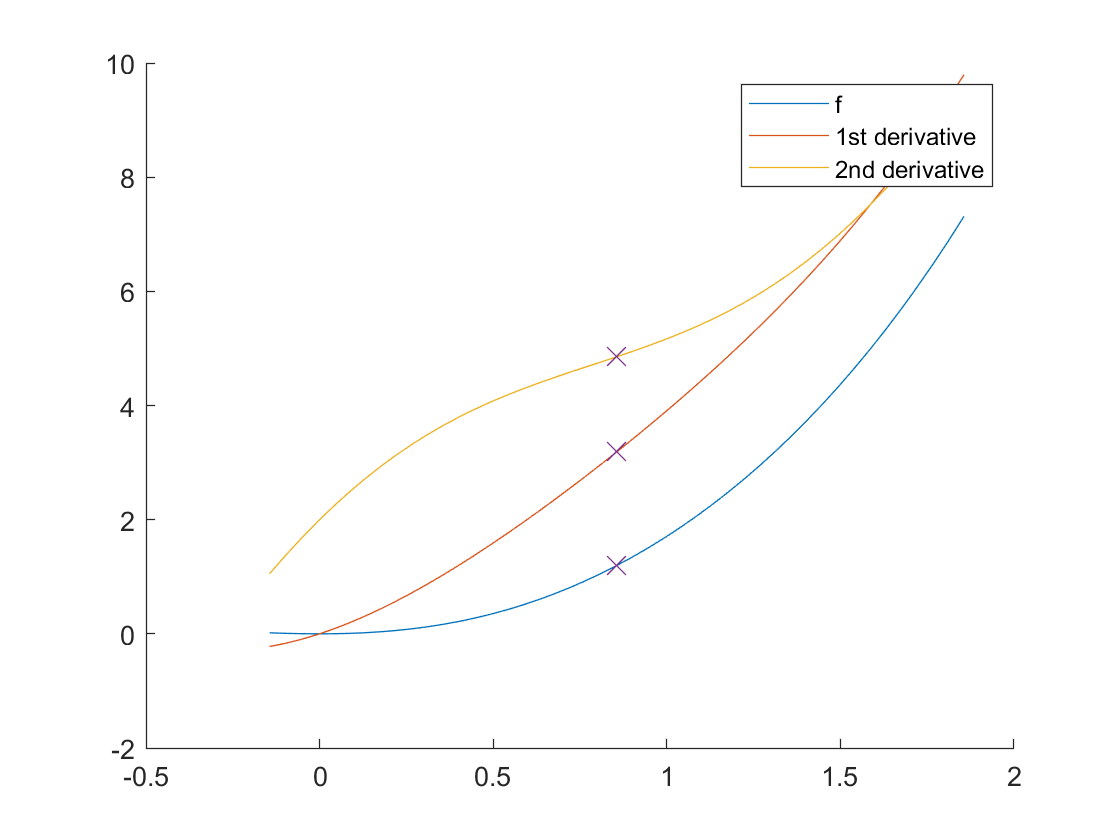

fig = figure();
ax = axes(fig);
ax.NextPlot = 'add';
fp1 = fplot(hf1, [a-1,a+1]);
fp2 = fplot(hf1_1, [a-1,a+1]);
fp3 = fplot(hf1_2, [a-1,a+1]);
plot([a,a,a],[hf1(a),hf1_1(a),hf1_2(a)], 'x', 'MarkerSize', 10);
legend([fp1,fp2,fp3], {'f', '1st derivative', '2nd derivative'})

## Analytical results

h = 1e-3;
standard_fval1 = hf1(a);
standard_fval1_1 = hf1_1(a);
standard_fval1_2 = hf1_2(a);
disp(['first derivative result: ',num2str(standard_fval1_1,15)])

first derivative result: 3.18787490507905


disp(['second derivative result: ',num2str(standard_fval1_2,15)])

second derivative result: 4.85437033819734


hf_error_1 = @(x) abs(x-standard_fval1_1)/abs(standard_fval1_1);
hf_error_2 = @(x) abs(x-standard_fval1_2)/abs(standard_fval1_2);

## First Derivative-1


$$$$
f\prime\left( a \right) =\frac{f\left( a+h \right) -f\left( a-h \right)}{2h}
$$
$$


ret1 = (hf1(a+h)-hf1(a-h))/2/h;
disp(['First Derivative-1: ',num2str(ret1,15)])

First Derivative-1: 3.18787524503306


disp(['relative error: ',num2str(hf_error_1(ret1))])

relative error: 1.0664e-07


## First Derivative-2


$$$$
f\prime\left( a \right) =\frac{f\left( a-2h \right) -8f\left( a-h \right) +8f\left( a+h \right) -f\left( a+2h \right)}{12h}
$$
$$


ret1 = (hf1(a-2*h) - 8*hf1(a-h) + 8*hf1(a+h) - hf1(a+2*h))/12/h;
disp(['First Derivative-2: ',num2str(ret1,15)])

First Derivative-2: 3.18787490507869


disp(['relative error: ',num2str(hf_error_1(ret1))])

relative error: 1.1019e-13


## Second Derivative-1


$$$$
f''\left( a \right) =\frac{f\left( a+h \right) +f\left( a-h \right) -2f\left( a \right)}{h^2}
$$
$$


ret1 = (hf1(a+h) + hf1(a-h) - 2*hf1(a))/h^2;
disp(['Second Derivative-1: ',num2str(ret1,15)])

Second Derivative-1: 4.85437043185044


disp(['relative error: ',num2str(hf_error_2(ret1))])

relative error: 1.9293e-08


## Second Derivative-2


$$$$
f''\left( a \right) =\frac{-f\left( a-2h \right) +16f\left( a-h \right) -30f\left( a \right) +16f\left( a+h \right) -f\left( a+2h \right)}{12h^2}
$$
$$


ret1 = (-hf1(a-2*h) + 16*hf1(a-h) -30*hf1(a) +16*hf1(a+h) - hf1(a+2*h))/12/h^2;
disp(['Second Derivative-2: ',num2str(ret1,15)])

Second Derivative-2: 4.85437033833265


disp(['relative error: ',num2str(hf_error_2(ret1))])

relative error: 2.7874e-11
